# Real-Time Video Stabilization Using Kalman Filter

本项目实现了基于**光流估计 + Kalman 滤波**的实时视频防抖算法[^1]，能够在视频播放时同时显示**防抖前后对比**效果。核心算法来源于光流法计算相邻帧的平移、旋转、缩放参数，并通过 Kalman 滤波器进行平滑，最终生成防抖后的稳定视频序列。

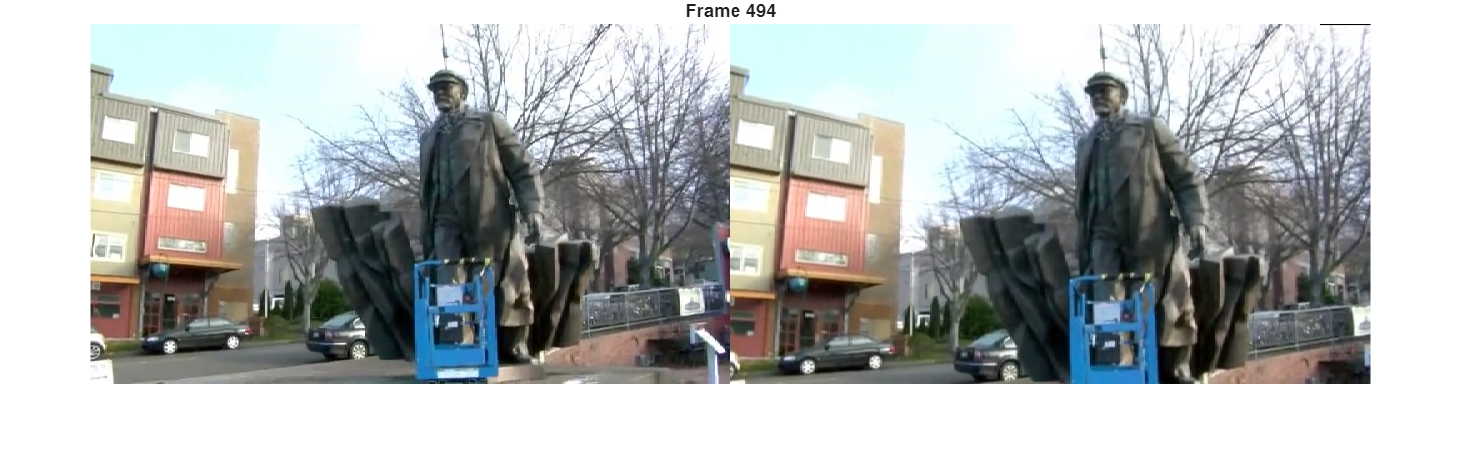


% 输入视频路径
videoPath = "./data/videoShake.m4v";  % 这里换成你的测试视频

% 读取视频
vReader = VideoReader(videoPath);

% 创建防抖对象
stab = VideoStab();

% 读取第一帧
if hasFrame(vReader)
    prevFrame = readFrame(vReader);
else
    error("视频为空");
end

frameCount = 0;
showObj = imshow([prevFrame,prevFrame]);
t = title(sprintf("Frame %d", frameCount));

while hasFrame(vReader)
    currFrame = readFrame(vReader);
    frameCount = frameCount + 1;

    % 调用 stabilize
    smoothedFrame = stab.stabilize(prevFrame, currFrame);

    % 拼接前后对比
    canvas = imtile({prevFrame,smoothedFrame},GridSize=[1,2]);

    % 如果分辨率太大可以缩放
    if size(canvas,2) > 1920
        scaleFactor = 1920 / size(canvas,2);
        canvas = imresize(canvas, scaleFactor);
    end

    % 显示
    showObj.CData = canvas;
    t.String = sprintf("Frame %d", frameCount);

    % 当前帧变为下一轮的 prevFrame
    prevFrame = currFrame;

    drawnow;
end

### References

[1] L. Kejriwal and I. Singh, "A Hybrid Filtering Approach of Digital Video Stabilization for UAV Using Kalman and Low Pass Filter," Procedia Computer Science, vol. 93, pp. 359-366, 2016, doi: 10.1016/j.procs.2016.07.221.

[2] [Stabilize Video Using Image Point Features](https://www.mathworks.com/help/vision/ug/video-stabilization-using-point-feature-matching.html)